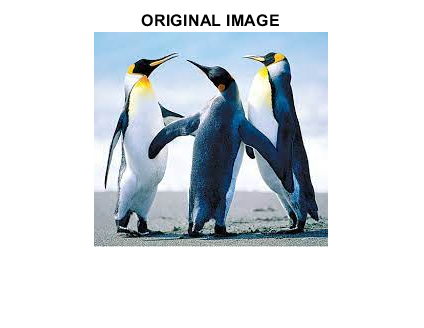

clc;clear;close all;

% Reading the penguine.jpg RGB image 
I = imread('penguine.jpg');
figure,imshow(I);title('ORIGINAL IMAGE');

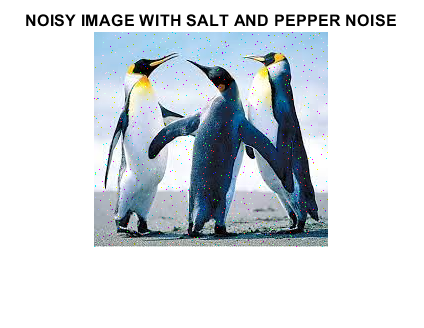



% calling function to add noise
[s,g,sp]=noise(I);

% salt and pepper noise
figure,imshow(s);title('NOISY IMAGE WITH SALT AND PEPPER NOISE');

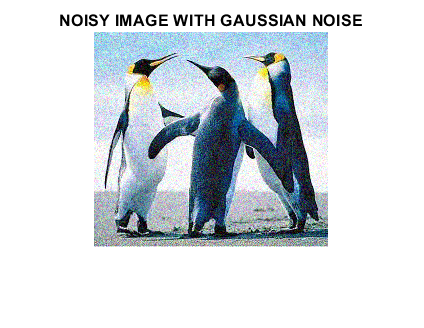


% Gaussian noise
figure,imshow(g);title("NOISY IMAGE WITH GAUSSIAN NOISE");

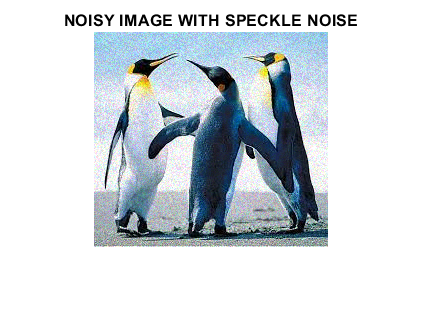

  
% Speckle noise
figure,imshow(sp);title("NOISY IMAGE WITH SPECKLE NOISE");

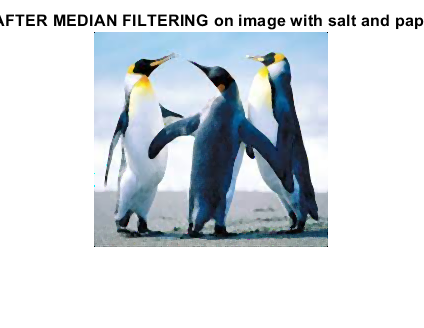


%Calling the filter function and showing the output
A=mediancust(s);
figure,imshow(A);title('IMAGE AFTER MEDIAN FILTERING on image with salt and paper noise');

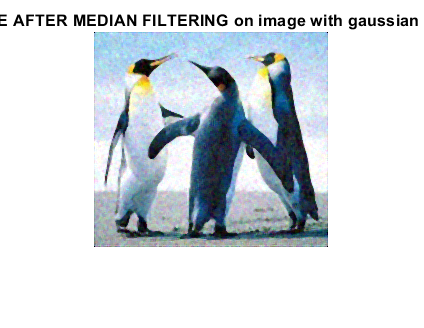


B=mediancust(g);
figure,imshow(B);title('IMAGE AFTER MEDIAN FILTERING on image with gaussian noise');

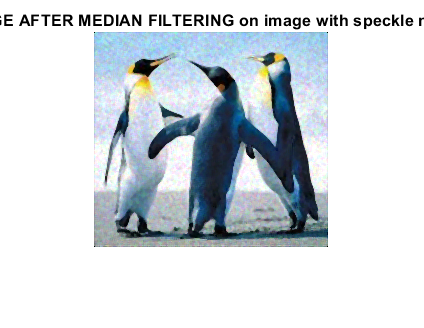


C=mediancust(sp);
figure,imshow(C);title('IMAGE AFTER MEDIAN FILTERING on image with speckle noise');


% Measure signal-to-noise ratio,peak signal-to-noise ratio and mean square
% error and printing them
[peaksnr1, snr1] = psnr(A, I);
fprintf('\n The Peak-SNR value of salt and paper noise filtered image with ref img is %0.4f', peaksnr1);


 The Peak-SNR value of salt and paper noise filtered image with ref img is 24.5911

fprintf('\n The SNR value of of salt and paper noise filtered image with ref img is %0.4f \n', snr1);


 The SNR value of of salt and paper noise filtered image with ref img is 21.5477 


err1 = immse(A(:,:,2), I(:,:,2));
fprintf('\n The mean-squared error of salt and paper noise filtered image with ref img is %0.4f\n', err1);


 The mean-squared error of salt and paper noise filtered image with ref img is 228.2508



[peaksnr2, snr2] = psnr(B, I);
fprintf('\n The Peak-SNR value of gaussian noise filtered image with ref img is %0.4f', peaksnr2);


 The Peak-SNR value of gaussian noise filtered image with ref img is 22.4943

fprintf('\n The SNR value of gaussian noise filtered image with ref img is %0.4f \n', snr2);


 The SNR value of gaussian noise filtered image with ref img is 19.4510 


err2 = immse(B(:,:,2), I(:,:,2));
fprintf('\n The mean-squared error of gaussian noise filtered image with ref imgis %0.4f\n', err2);


 The mean-squared error of gaussian noise filtered image with ref imgis 370.1122



[peaksnr3, snr3] = psnr(C, I);
fprintf('\n The Peak-SNR value of speckle noise filtered image with ref img is %0.4f', peaksnr3);


 The Peak-SNR value of speckle noise filtered image with ref img is 23.1812

fprintf('\n The SNR value of speckle noise filtered image with ref img is %0.4f \n', snr3);


 The SNR value of speckle noise filtered image with ref img is 20.1378 


err3 = immse(C(:,:,2), I(:,:,2));
fprintf('\n The mean-squared error of speckle noise filtered image with ref imgis %0.4f\n', err3);


 The mean-squared error of speckle noise filtered image with ref imgis 317.5614
